# Simulate a Mobile Robot in a Warehouse Using Gazebo

This example shows how to simulate a warehouse robot in Gazebo. Gazebo enabled you to simulate a mobile robot that uses a range sensor, while executing certain tasks in a simulated environment. This example details how to use a simulator to apply the [Execute Tasks for A Warehouse Robot](docid:robotics_ug.mw_0c16e017-b9af-4684-94d7-ca6430f0aec3) example, where a robot delivers packages in a warehouse scenario. The robot makes use of the simulated range sensor in Gazebo to detect possible collisions with a dynamic environment and avoid them.

**Prerequisites**

- Download a [Virtual Machine with ROS and Gazebo](https://www.mathworks.com/support/product/robotics/ros2-vm-installation-instructions-v5.html) to set up a simulated robot.

- Review the [Execute Tasks for A Warehouse Robot](docid:robotics_ug.mw_0c16e017-b9af-4684-94d7-ca6430f0aec3) example for the workflow of path planning and navigating in a warehouse scenario.

- Review the [Control a Differential Drive Robot in Simulink and Gazebo](docid:robotics_ug.mw_ea28eff9-a4e4-4c5c-9a96-de7a21e4ed4d) example for basic steps of collecting sensor data and controlling a robot in Gazebo.

## Model Overview

Open the model.

open_system('simulateWarehouseRobotInGazebo.slx')

The model can be divided into the following elements:

- **Sense:** Read data from sensors in Gazebo.

- **Schedule: **Assign packages and plan paths for robots to deliver the packages.

- **Control:** Generate commands to follow the predefined path and avoid obstacles.

- **Actuate:** Send commands to Gazebo to actuate the robot in the environment.

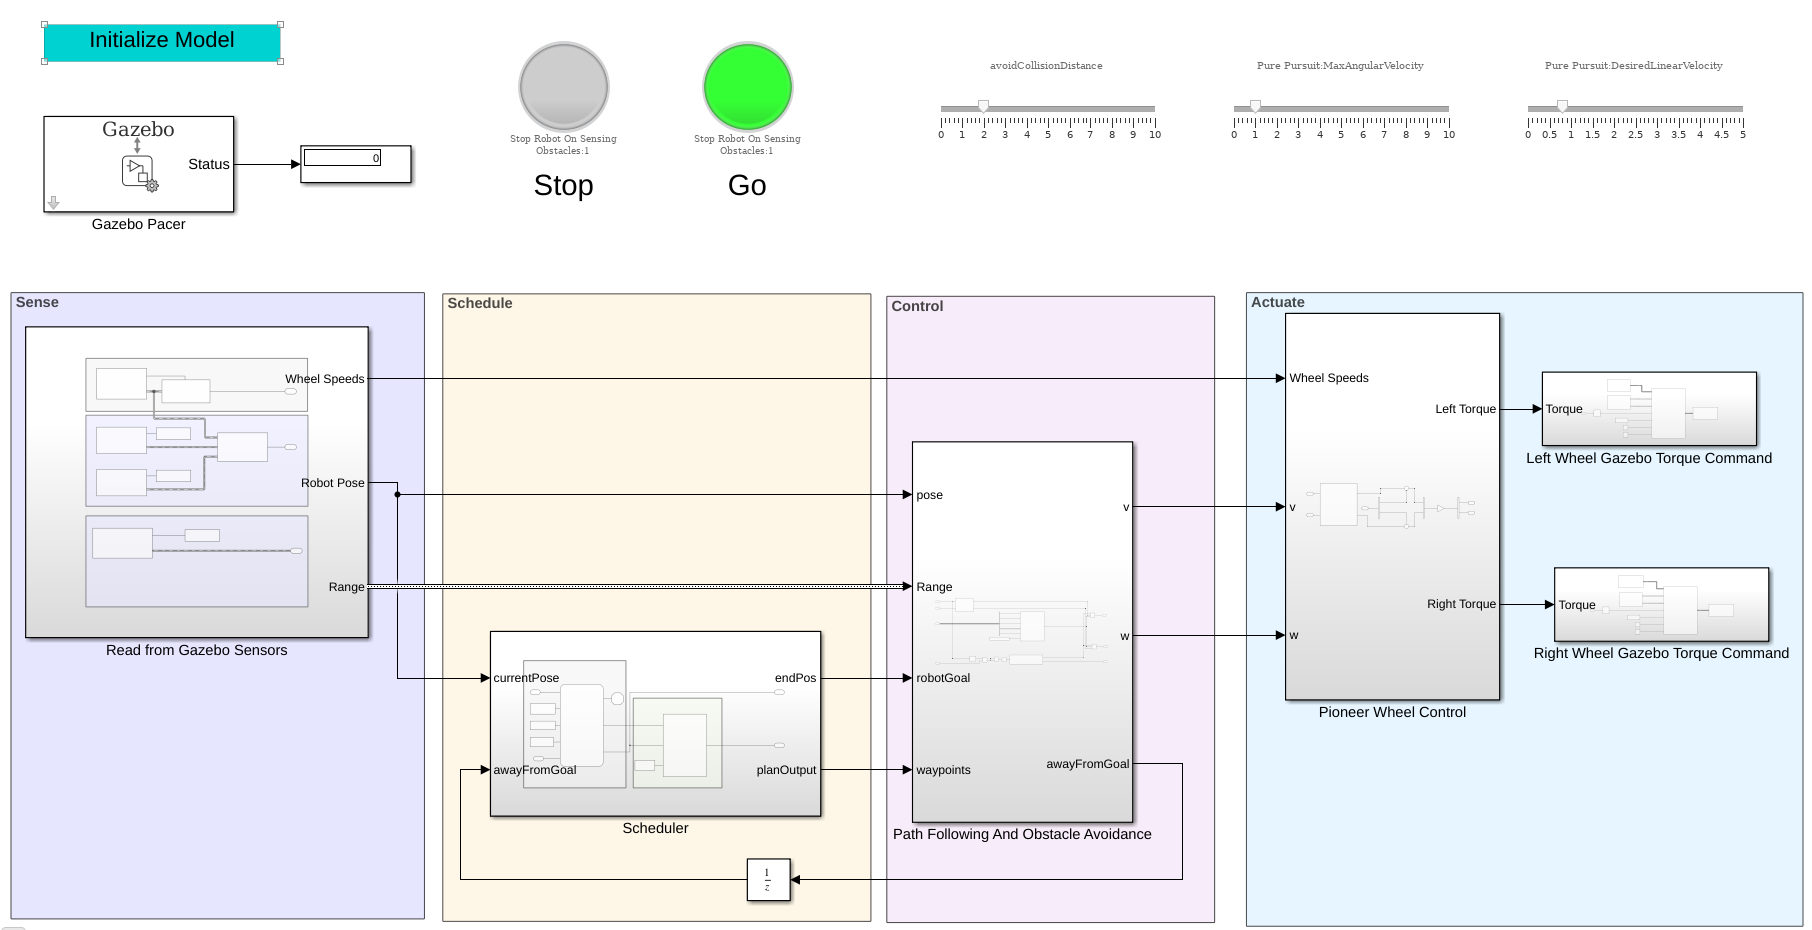

### Schedule

The robot performs the task of going between the charging station, the loading station, and the unloading station as guided by the **Scheduler**.

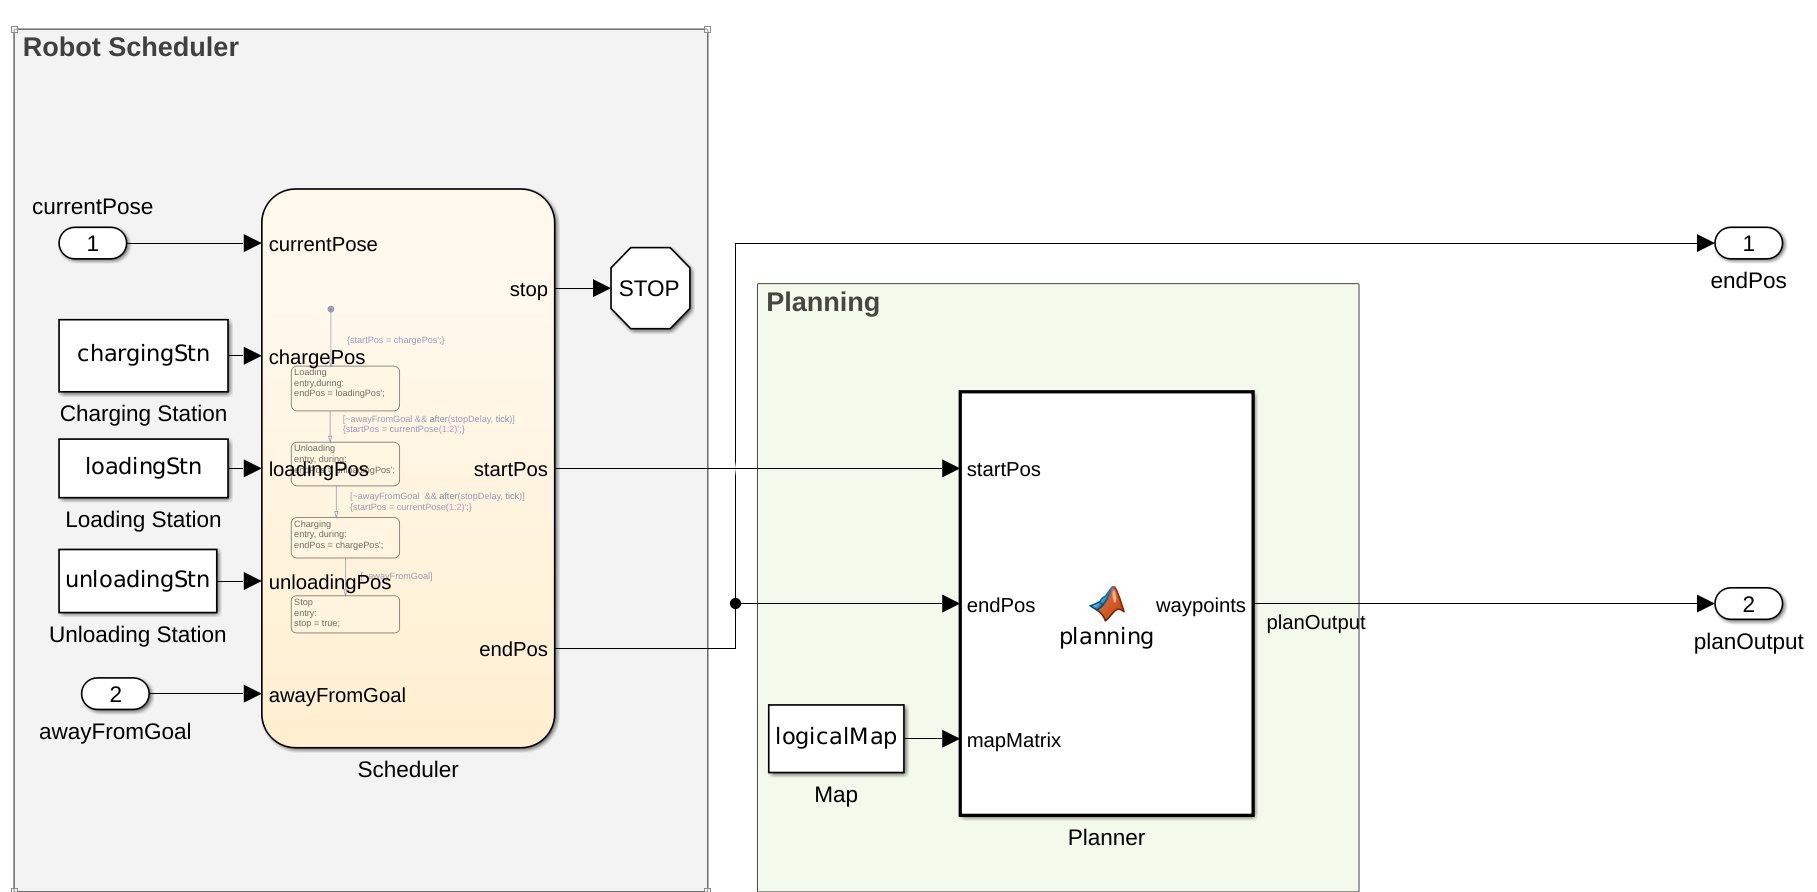

### Sense

The current robot pose, the wheel speeds, and the range sensor readings are read from the simulated environment in Gazebo. The figure below is the expanded view of the **Read From Gazebo Sensors** subsystem.

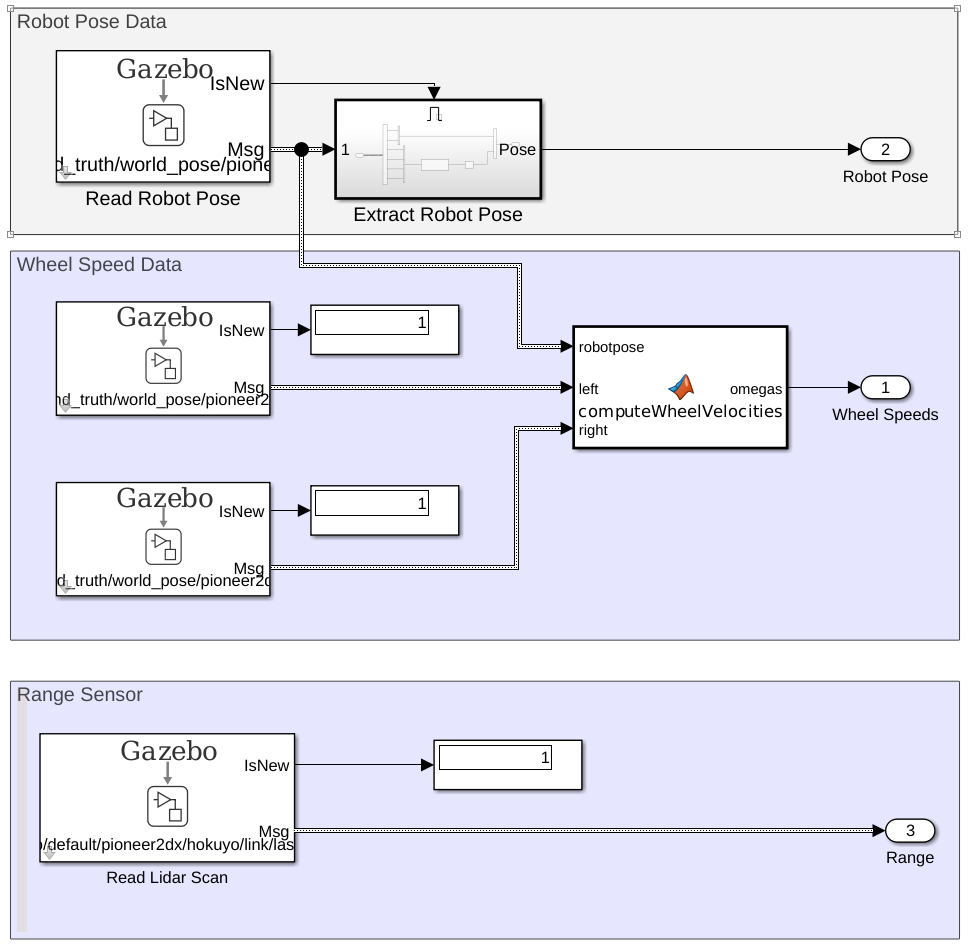

### Control

The controller generates control commands for following the waypoints using the **Pure Pursuit** block. If the range sensor on the robot detects an obstacle within the `avoidCollisionDistance` threshold, the robot stops. Also, the robot stops when gets near enough to the goal.

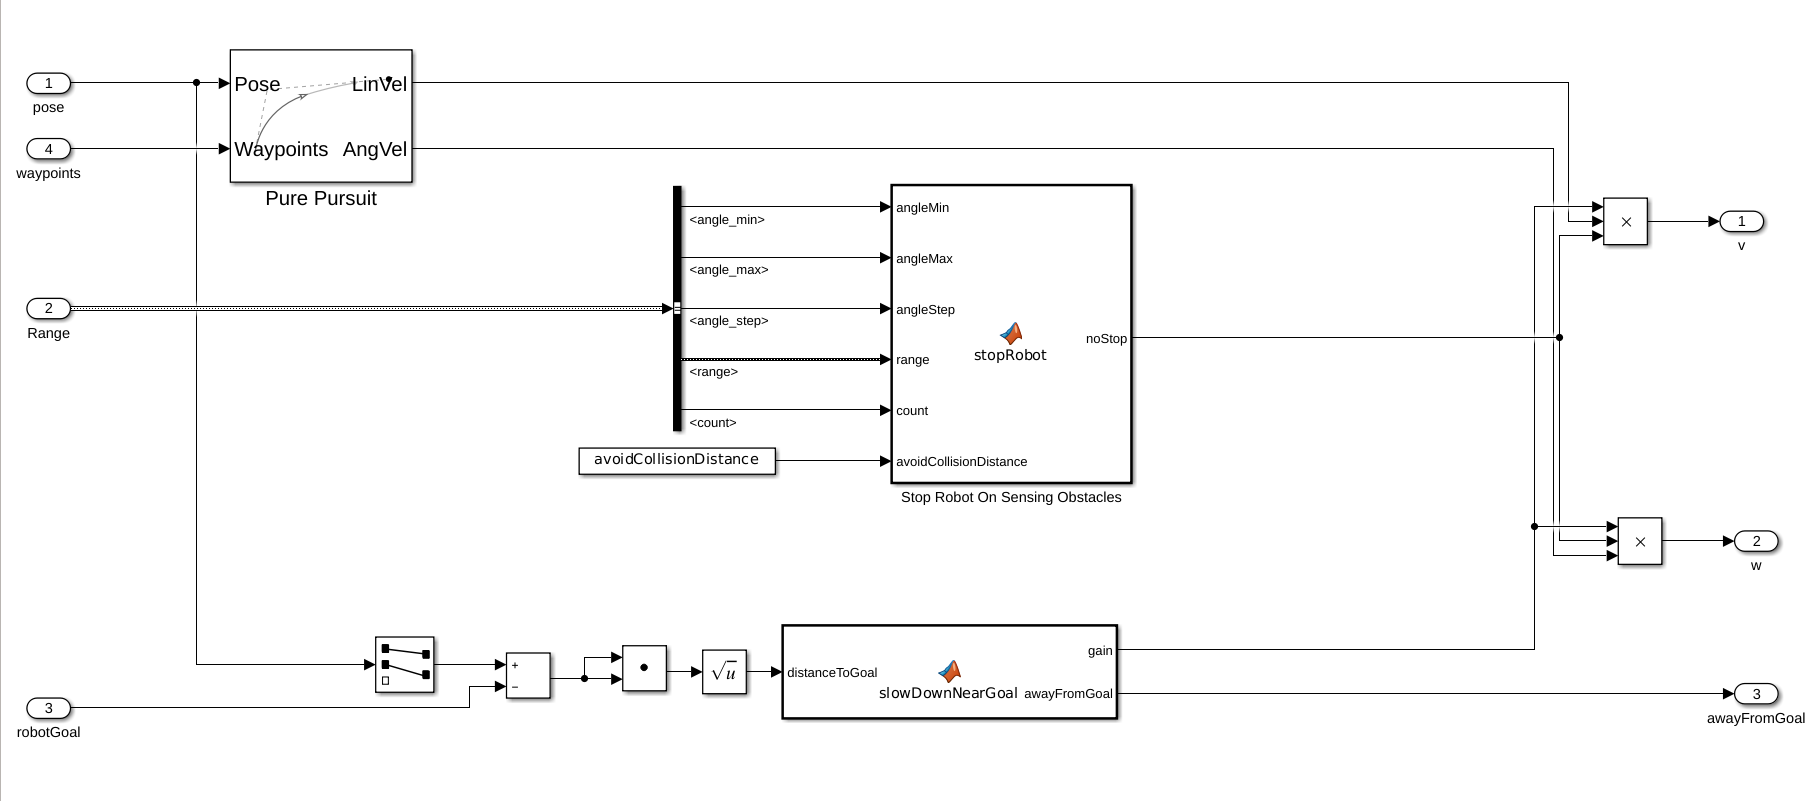

### Actuate

Based on the generated control commands, the **Pioneer Wheel Control** subsystem generates a torque value for each wheel. The torque is applied as an `ApplyJointTorque` command.

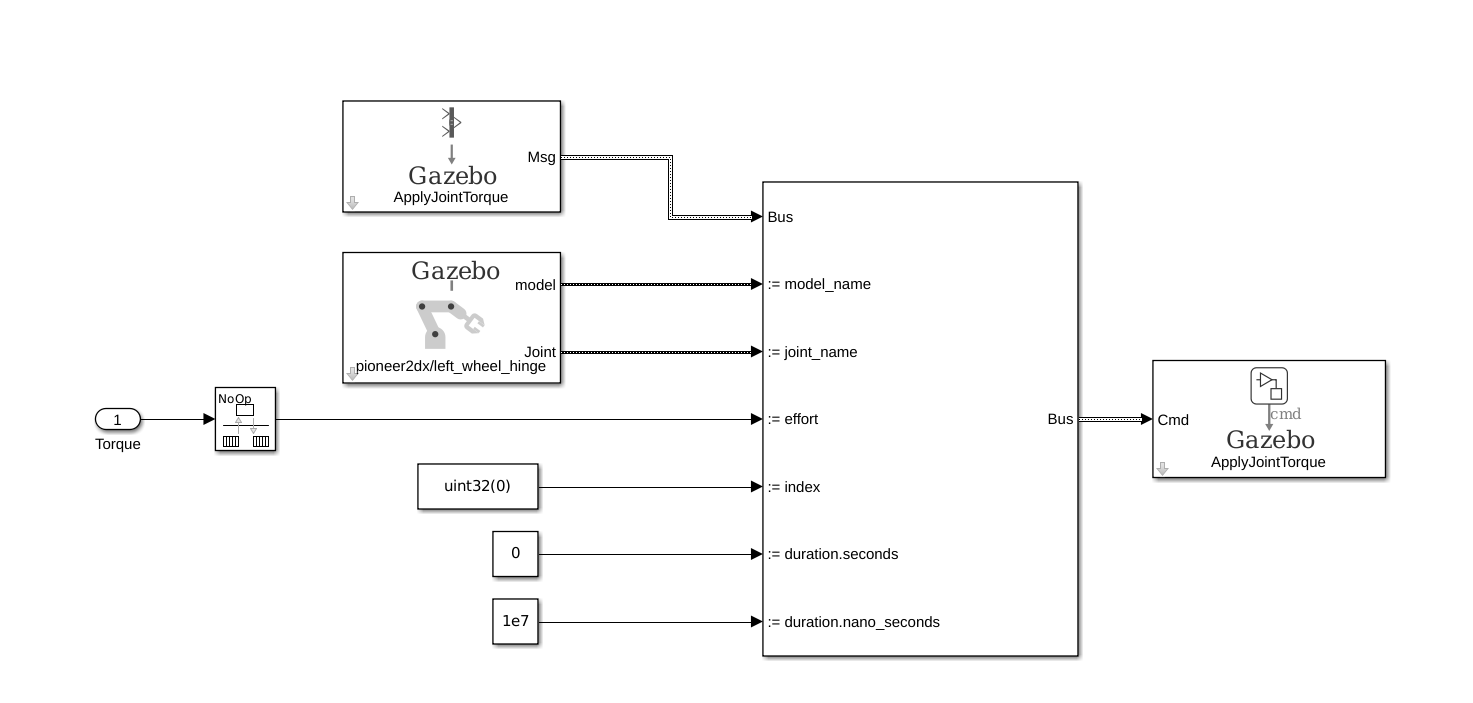

## Setup

### Warehouse Facility

Load the example map file, `map`, which is a matrix of logical values indicating occupied space in the warehouse. Invert this matrix to indicate free space, and make a `binaryOccupancyMap` object. Specify a resolution of 100 cells per meter.

The map is based off of the `warehouseExtensions.world` file, which was made using the Building Editor on the same scaling factor as mentioned below. A `.png` file for the map can be made using the `collision_map_creator_plugin` plugin to generate the map matrix. The details on how to install the plugin can be found at [Collision Map Creator Plugin](https://classic.gazebosim.org/tutorials?tut=custom_messages&cat=transport). 

mapScalingFactor = 100;
load gazeboWarehouseMap.mat map
logicalMap = ~map;
map = binaryOccupancyMap(logicalMap,mapScalingFactor);
show(map)

 Assign the *xy*-locations of the charging station, sorting station, and the unloading location near shelves in the warehouse. The values chosen are based on the simulated world in Gazebo.

chargingStn = [12,5];
loadingStn = [24,5];
unloadingStn = [15,24];

Show the various locations on the map.

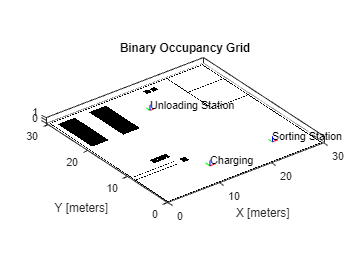

hold on;

text(chargingStn(1), chargingStn(2), 1, 'Charging');
plotTransforms([chargingStn, 0], [1 0 0 0])

text(loadingStn(1), loadingStn(2), 1, 'Sorting Station');
plotTransforms([loadingStn, 0], [1 0 0 0])

text(unloadingStn(1), unloadingStn(2), 1, 'Unloading Station');
plotTransforms([unloadingStn, 0], [1 0 0 0])

hold off;

### Range Sensor

The **Read Lidar Scan** block in the Sensing section is used to read the range values from the simulated range sensor. The `warehouseExtensions.world` file contains the details of the various models and actors (warehouse workers) in the scene. Because <`actor>` tags are static links with only visual meshes, the sensor type of the range sensor is `gpu_ray`.

Additionally, the range sensor uses 640 range, but the default is 128. This requires modification of the buses used in the in the **Read Lidar Scan** block. Load the `exampleHelperWarehouseRobotWithGazeboBuses.mat` file to get a modified bus with `Gazebo_SL_Bus_gazebo_msgs_LaserScan.range` set to 640. The modified buses were saved to a `.mat` file using the Type Editor.

load exampleHelperWarehouseRobotWithGazeboBuses.mat

## Collision Avoidance

The actors in the world are walking a predefined trajectory. The robot makes use of a range sensor to check for obstacles within a range of 2.0 m (`avoidCollisionDistance)`  with range angles from `[-pi/10, pi/10]` Upon a non-zero reading within that range and view, the robot stops and only resumes after the range is clear. The "Stop Robot On Sensing Obstacles" function block incorporates this logic. 

While running the simulation, the **Stop **lamp turns green when the robot senses that it is good to proceed. If it has stopped the lamp turns red. 

avoidCollisionDistance = 2; 

## Simulate 

To simulate the scenario, set up the connection to Gazebo. 

First, run the Gazebo Simulator. In the virtual machine, click the **Gazebo Warehouse Robot **icon. If the Gazebo simulator fails to open, you may need to reinstall the plugin. See **Install Gazebo Plugin** **Manually** in [Perform Co-Simulation between Simulink and Gazebo](docid:robotics_ug.mw_1054c688-ce70-4924-bce3-2c404f798257).

In Simulink, open the **Gazebo Pacer** block and click **Configure Gazebo network and simulation settings**. Specify the **Network Address** as **Custom**,  the **Hostname/IP Address** for your Gazebo simulation, and a **Port** of `14581`, which is the default port for Gazebo. The desktop of the VM displays the IP address.

For more information about connecting to Gazebo to enable co-simulation, see [Perform Co-Simulation between Simulink and Gazebo](docid:robotics_ug.mw_1054c688-ce70-4924-bce3-2c404f798257).

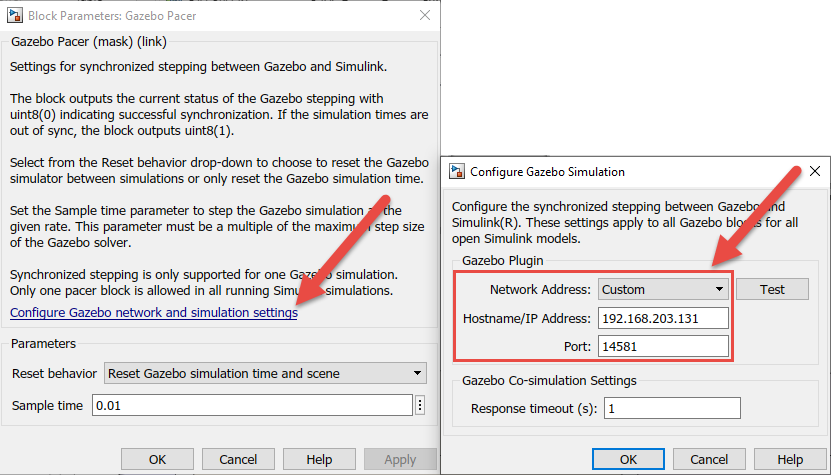

Click the **Initialize Model** button at the top of the model to initialize all the variables declared above. 

**Run** the simulation. The robot drives around the environment and stops whenever a worker gets within the defined threshold. 

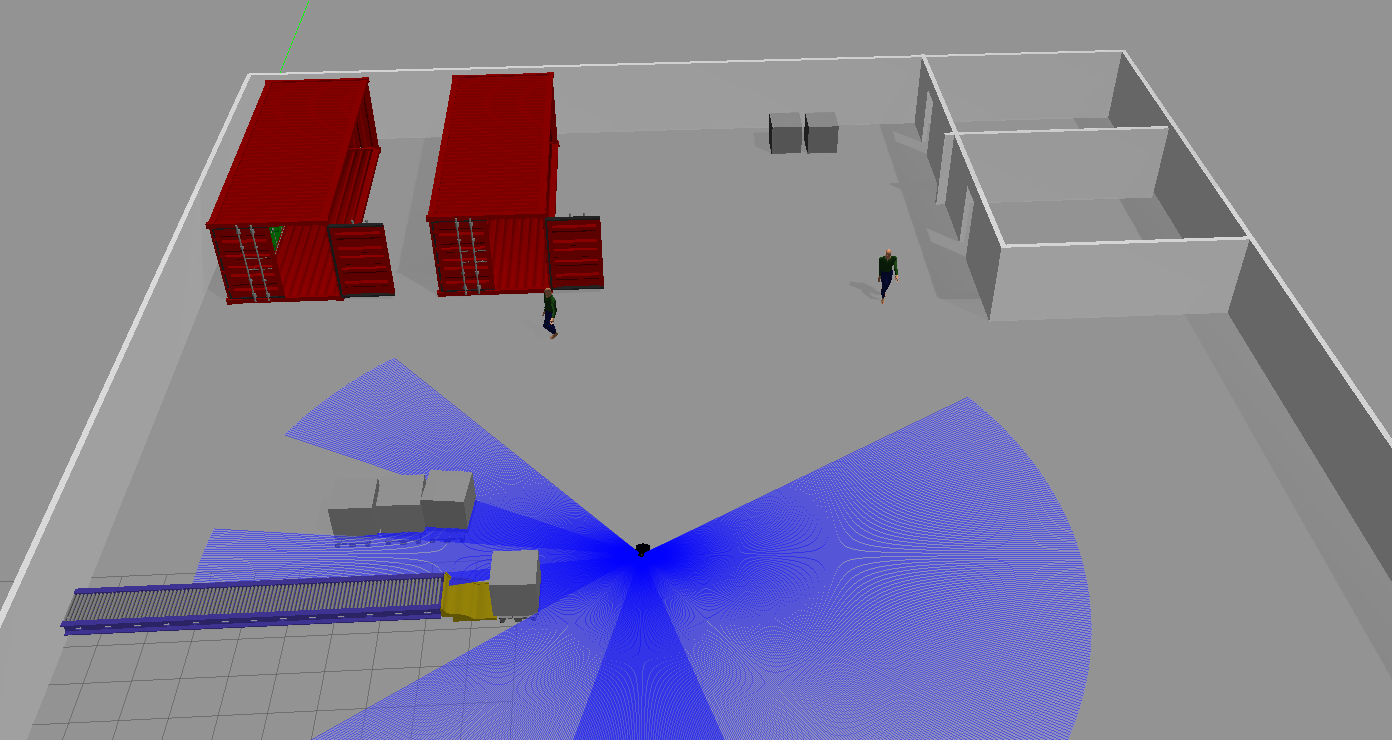

*Copyright 2019 The MathWorks, Inc.*